# Specify Space Between Paragraphs

These examples show how to specify the space between DOM `Paragraph` objects in a document. To set the spacing, modify a `Paragraph` object  `Style` property, or create a paragraph style in a document template. 

## Setting the Style Programmatically

In this example, paragraph spacing is set programmatically by including `OuterMargin` objects in the `Style` property of each paragraph. The following output is created:

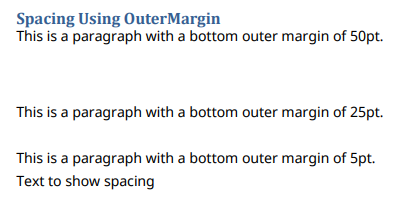

Import the DOM package so you do not have to use long, fully qualified class names.

import mlreportgen.dom.*

Create and open a document. To create a Word document, change the output type from `"pdf"` to `"docx"`. To create an HTML document, change `"pdf" `to `"html" `or `"html-file"` for a multi-file or single-file document, respectively. Append a heading to describe the example.

d = Document("myDoc1", "pdf");
open(d);

append(d, Heading1("Spacing Using OuterMargin"));

Create a paragraph and set its `Style` to include an `OuterMargin` object. Set the left, right, and top outer margins to 0 points, and the bottom margin to 50 points. Append the paragraph to the document.

p1 = Paragraph("This is a paragraph with a bottom outer margin of 50pt.");
p1.Style = {OuterMargin("0pt", "0pt","0pt","50pt")};

append(d, p1);

Create two more paragraphs with different bottom margins. Append the paragraphs to the document along with a final text object so that the bottom margin of the last paragraph can be seen.

p2 = Paragraph("This is a paragraph with a bottom outer margin of 25pt.");
p2.Style = {OuterMargin("0pt", "0pt","0pt","25pt")};
append(d, p2);

p3 = Paragraph("This is a paragraph with a bottom outer margin of 5pt.");
p3.Style = {OuterMargin("0pt", "0pt","0pt","5pt")};
append(d, p3);

append(d, Text("Text to show spacing"));

Close and view the document.

close(d);
rptview(d);

## Using a Style in a Template

In this example, paragraphs use styles defined in a custom template file used by the document. The following output is created:

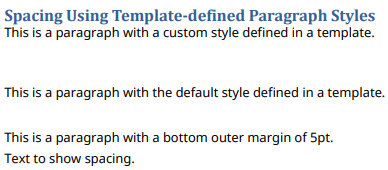

Import the DOM package so you do not have to use long, fully qualified class names.

import mlreportgen.dom.*

Create and open a PDF document. Specify a custom document template named `exampleTemplate` when creating the `Document` object. To make Word or HTML documents, first create a Word or HTML template. Then, change `"pdf"` to `"docx"`, `"html"`, or `"html-file"` depending on the template created.

See [Create an HTML or PDF Template](https://www.mathworks.com/help/rptgen/ug/create-an-html-or-pdf-template.html) or [Create a Microsoft Word Template](https://www.mathworks.com/help/rptgen/ug/create-a-microsoft-word-template.html) for details on how to create templates.

d = Document("myDoc2", "pdf", "exampleTemplate");

The custom PDF template `exampleTemplate` has been modified to contain a paragraph style named `exampleParagraphStyle` defined in `exampleTemplate\stylesheets\root.css` as the following:

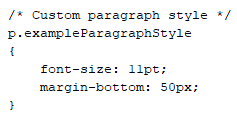

The `margin-bottom` value gives paragraphs a bottom margin of 50 points, similar to the previous example. Alternatively, you can modify the default paragraph style in the template so that paragraphs in the document automatically have the custom style. The default paragraph style in `exampleTemplate` has been modified to have a bottom margin of 25 points:

Open the document and append a heading to describe the example.

open(d);

append(d, Heading1("Spacing Using Template-defined Paragraph Styles"));

Create a paragraph using `exampleParagraphStyle` as the style name. Create another paragraph with no style name specified so that it uses the default paragraph style in the template.

p1 = Paragraph("This is a paragraph with a custom style defined in a template.", ...
    "exampleParagraphStyle");

p2 = Paragraph("This is a paragraph with the default style defined in a template.");

Create another paragraph with the default paragraph style, but set its `Style` property to have a different bottom margin. This will override the template's default style.

p3 = Paragraph("This is a paragraph with a bottom outer margin of 5pt.");
p3.Style = {OuterMargin("0pt", "0pt","0pt","5pt")};

Append the paragraphs to the document along with a final text object so that the bottom margin of the last paragraph can be seen.

append(d, p1);
append(d, p2);
append(d, p3);
append(d, Text("Text to show spacing."));

Close and view the document.

close(d);
rptview(d);

*Copyright 2018 The MathWorks, Inc.*